# KINEMATIC ANALYSIS OF FOUR BAR MECHANISM

**IF COUPLER IS THE DRIVER LINK**

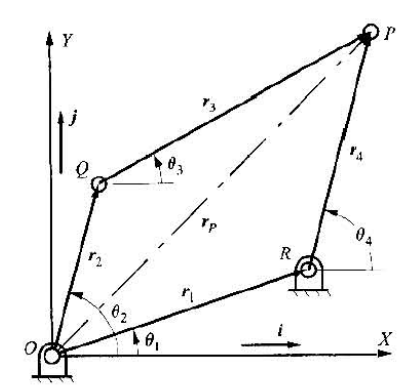

**GIVEN VALUES**

L1 = 100;
L2 = 45;
L3 = 55;
L4 = 56;
theta_1 = 10;
theta_3 = 10;

**INTIAL CONDITIONS**

angle_2 = 55;
angle_4 = 70;
iter = 0;
sol = [angle_2;angle_4];

**POSITION ANALYSIS**


while iter < 1000
    
    f = [(L1*cos(theta_1) - L2*cos(theta_3) - L3*cos(sol(1)) + L4*cos(sol(2)));
         (L1*sin(theta_1) - L2*sin(theta_3) - L3*sin(sol(1)) + L4*sin(sol(2)))];
    
    df = [(L3*sin(sol(1))), (-L4*sin(sol(2))) ;
          (-L3*cos(sol(1))), (L4*cos(sol(2)))];
    
    sol = sol - (df\f);
    
    iter = iter + 1;

end

theta_2 = sol(1)

theta_2 = 55.0506

theta_4 = sol(2)

theta_4 = 68.6536

**VELOCITY ANALYSIS**


w3 = 10.5;          % In rad/s

% Position vectors
rAB = [L2*cos(theta_2) L2*sin(theta_2) 0]./1000;
rBC = [L3*cos(theta_3) L3*sin(theta_3) 0]./1000;
rDC = [L4*cos(theta_4) L4*sin(theta_4) 0]./1000;

k = [0 0 1];

syms w2 w4

V_P = w2*cross(k,rAB);
% Magnitude of velocity at point B


V_Q1 = V_P + w3*cross(k,rBC);
V_Q2 = w4*cross(k,rDC);

eqn_vel = V_Q1 - V_Q2 == 0;
S = solve(eqn_vel,[w2 w4]);

w2 = double(S.w2)

w2 = -12.8333

w4 = double(S.w4)

w4 = -10.5000


V_C = double(subs(V_Q2,w4));
V_P = double(subs(V_P,w2));
Vel_mag_C = norm(V_C,2) 

Vel_mag_C = 0.5880

Vel_mag_P = norm(V_P,2)

Vel_mag_P = 0.5775

**ACCELERATION ANALYSIS**


alpha_3 = -26;             % In rad/s2
syms alpha_2 alpha_4
a_P = (alpha_2*cross(k,rAB)) - ((w2)^2)*rAB;
             
a_Q1 = a_P + alpha_3*cross(k,rBC) - ((w3)^2)*rBC;
a_Q2 = alpha_4*cross(k,rDC) - ((w4)^2)*rDC;

eqn_acc = a_Q1 - a_Q2 == 0;
R = solve(eqn_acc,[alpha_2 alpha_4]);

alpha2 = double(R.alpha_2)

alpha2 = -109.9136

alpha4 = double(R.alpha_4)

alpha4 = 175.1444


a_Q = double(subs(a_Q2,alpha4));
a_P = double(subs(a_P,alpha2));
acc_mag_C = double(norm(a_Q,2)) 

acc_mag_C = 11.5895

acc_mag_P = double(norm(a_P,2))% Magnitude of acceleration at point C

acc_mag_P = 8.9101